## Lecture 7

format shortg

**9.2.2**

A hypothesis will be used to test that a population mean equals 5 against the alternative that the population mean is less than 5 with known variance σ. What is the critical value for the test statistic $Z_{0\;}$ for the following significance levels?

a. $\alpha =$0.01 

a = norminv(0.01)

a = -2.3263

b. $\alpha =$0.05 

b = norminv(0.05)

b = -1.6449

c. $\alpha =$0.10

c = norminv(0.1)

c = -1.2816

**9.2.3**

Output from a software package follows:

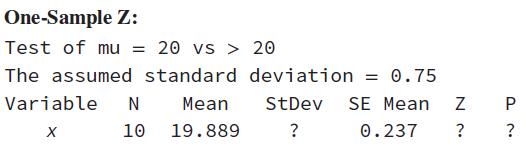

a. Fill in the missing items. What conclusions would you draw?

SE mean (Standard error mean)


$$\sigma_{\bar{x} } =\frac{\sigma }{\sqrt{n}}\;$$



$$z_0 =\frac{\bar{X} -\mu_0 \;}{\frac{\sigma }{\sqrt{n}}\;}$$


semean = 0.237; n = 10; mean = 19.889; mu_0 = 20;
stdev = semean*sqrt(n)

stdev = 0.7495

z = (mean-mu_0)/(stdev/sqrt(n))

z = -0.4684

p = normcdf(z, 'upper') % Upper means you want everything to the right

p = 0.6802

b. Is this a one-sided or a two-sided test?

It is a onesided test since the alternative is on $\mu <20$

c. Use the normal table and the preceding data to construct a 95% two-sided CI on the mean.

z_frak = norminv(1-(0.05/2)) % We do this because we need 95% of each side.

z_frak = 1.9600

c_upper = mean + (stdev/sqrt(n))*z_frak

c_upper = 20.3535

c_lower = mean - (stdev/sqrt(n))*z_frak

c_lower = 19.4245


$$19\ldotp 4245<\mu <20\ldotp 3535$$


d. What would the P-value be if the alternative hypothesis is $H_1 :\mu \;\not= 20$?

d = 2* (1 - p)

d = 0.6395

**9.2.4**

For the hypothesis test $H_{0\;} :\mu \;=10$ against $H_1 :\mu >10$ and variance known, calculate the P-value for each of the following test statistics.

a. $z_{0\;}$ = 2.05 

a_p = normcdf(2.05, 'upper')

a_p = 0.0202

b. $z_{0\;}$ = −1.84 

b_p = normcdf(-1.84, 'upper')

b_p = 0.9671

c. $z_{0\;}$ = 0.4

c_p = normcdf(0.4, 'upper')

c_p = 0.3446

**9.2.6a**

A manufacturer produces crankshafts for an automobile engine. The crankshafts wear after 100,000 miles (0.0001 inch)

is of interest because it is likely to have an impact on warranty claims. A random sample of n = 15 shafts is tested and $\bar{X}$ = 2.78.

It is known that σ = 0.9 and that wear is normally distributed. 

a. Test $H_{0\;} :\mu =3$ versus $H_1 :\mu \;\not= \;3$ using $\alpha =0\ldotp 05$.


$$z_0 =\frac{\bar{X} -\mu_0 \;}{\frac{\sigma }{\sqrt{n}}\;}$$


xBar = 2.78; n = 15; stdev = 0.9; mu_0 = 3;
z_0 = (xBar-mu_0)/(stdev/sqrt(n))

z_0 = -0.9467

z_frak = norminv(1-(0.05/2)) % We do this because we need 95% of each side.

z_frak = 1.9600

Reject $H_{0\;}$if $z_{0\;} <-z_{\frac{\alpha }{2}} \;\mathrm{where}\;\alpha =0\ldotp 05\;\mathrm{and}-z_{0\ldotp 025} =-1\ldotp 96\;\mathrm{or}\;z_{0\;} >z_{\frac{\alpha }{2}} \;\mathrm{where}\;\alpha =0\ldotp 05\;\mathrm{and}z_{0\ldotp 025} =-1\ldotp 96$  

Since $-0\ldotp 95>-1\ldotp 96$, we fail to reject the null hypothesis. There is not sufficient evidence to support the claim the mean crankshaft wear differs from 3 at$\alpha =0\ldotp 05$

**9.2.7**

The life in hours of a battery is known to be approximately normally distributed with standard deviation $\sigma =1\ldotp 25$ hours. A random sample of 10 batteries has a mean life of $x=40\ldotp 5$ hours.

a. Is there evidence to support the claim that battery life exceeds 40 hours? Use $\alpha =0\ldotp 05$.

xBar = 40.5; stdev = 1.25; n = 10; mu_0 = 40;
z_0 = (xBar-mu_0)/(stdev/sqrt(n))

z_0 =        1.2649



alpha = 0.05;
z_alpha = norminv(1-alpha)

z_alpha =        1.6449


Reject $H_{0\;}$if $z_0 >z_{\alpha \;} \mathrm{where}\;z_0 =1\ldotp 2649\;\mathrm{and}\;z_{\alpha \;} =1\ldotp 6449$

This means that $H_0$ is accepted therefore we support the claim

b. What is the P-value for the test in part (a)?

p = normcdf(z_0, 'upper') % Upper means you want everything to the right

p =       0.10295


c. What is the β-error for the test in part (a) if the true mean life is 42 hours?


$$\delta =\mu -{\mu \;}_0$$


The $\Phi \;$is normcdf.

Since it is onesided and we want the positive side, I only use half of the equation.

mu = 40; mu_0 = 42;
delta = mu - mu_0

delta =     -2


betainput = z_alpha + ((delta*sqrt(n))/stdev)

betainput =       -3.4148


beta = normcdf(betainput)

beta =    0.00031916


d. What sample size would be required to ensure that β does not exceed 0.10 if the true mean life is 44 hours?


$$n\simeq \frac{{\left(z_{\alpha } +z_{\beta \;} \right)}^2 \sigma^2 }{\delta^2 \;}\;\mathrm{where}\;\delta =\mu -\mu_0$$


z_beta = norminv(1-0.1)

z_beta =        1.2816



mu = 40; mu_0 = 44;
z_alpha = norminv(1-alpha);
delta = mu - mu_0;
n = (((z_alpha + z_beta)^2)*stdev^2)/delta^2

n =       0.83631


e. Explain how you could answer the question in part (a) by calculating an appropriate confidence bound on battery life.

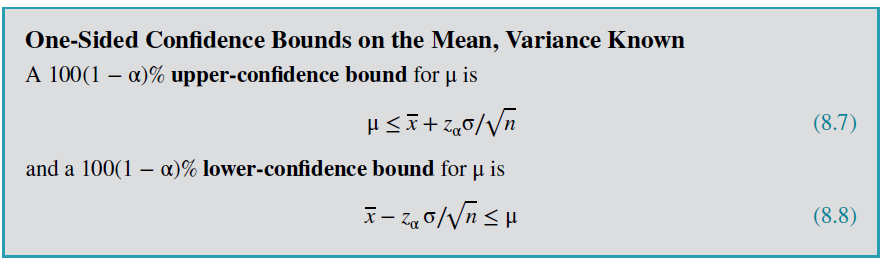

Since it is onesided we need to use this .

**9.3.1**

A hypothesis will be used to test that a population mean equals 10 against the alternative that the population mean is

greater than 10 with unknown variance. What is the critical value for the test statistic T0 for the following significance levels?

a. α = 0.01 and n = 20 

b. α = 0.05 and n = 12

c. α = 0.10 and n = 15

**9.3.7**

An article in Growth: A Journal Devoted to Problems of Normal and Abnormal Growth [“Comparison of Measured and Estimated Fat-Free Weight, Fat, Potassium and Nitrogen of Growing Guinea Pigs” (1982, Vol. 46(4), pp. 306–321)] reported the results of a study that measured the body weight (in grams) for guinea pigs at birth.

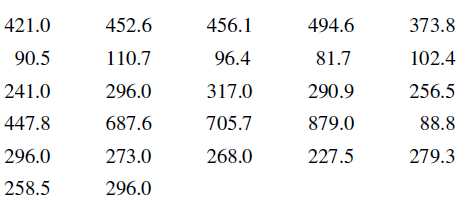

a. Test the hypothesis that mean body weight is 300 grams.Use $\alpha =0\ldotp 5$.

b. What is the smallest level of significance at which you would be willing to reject the null hypothesis?

c. Explain how you could answer the question in part (a) with a two-sided confidence interval on mean body weight.

**9.4.1**

Consider the test of $H_0 :\sigma {\;}_2 =7$ against $H_1 :\sigma_2 \;\;\not= \;7$. What are the critical values for the test statistic $X_{0\;}^2$ for the following

significance levels and sample sizes?

a. α = 0.01 and n = 20 

b. α = 0.05 and n = 12

c. α = 0.10 and n = 15

**9.4.3 **

The data fromMedicine and Science in Sports and Exercise described in Exercise 8.3.4 considered ice hockey player performance

after electrostimulation training. In summary, there were 17 players, and the sample standard deviation of performance was

0.09 seconds.

a. Is there strong evidence to conclude that the standard deviation of performance time exceeds the historical value of 0.75 seconds? Use $\alpha =0\ldotp 05$. Find the P-value for this test.

b. Discuss how part (a) could be answered by constructing

a 95% one-sided confidence interval for σ.

**9.5.2**

Suppose that of 1000 customers surveyed, 850 are satisfied or very satisfied with a corporation’s products and services.

a. Test the hypothesis $H_{0\;} :p=0\ldotp 9$ against $H_1 :p\;\not= \;0\ldotp 9$H1: p ≠ 0.9 at α = 0.05. Find the P-value.

b. Explain how the question in part (a) could be answered by constructing a 95% two-sided confidence interval for p.